clear
clc
clf

traj = load('proj1_flight_trajectory.dat');

%%%converting from ecef to local
ecef = lla2ecef(traj(:,2),traj(:,3),traj(:,4));
ecefrel = ecef - ecef(1,:);
lat = traj(1,2)

lat = 0.6939

long = traj(1,3)

long = -1.4695


dcm = [-sin(long) cos(long) 0;...
    -sin(lat)*cos(long) -sin(lat)*sin(long) cos(lat);...
    cos(lat)*cos(long) cos(lat)*sin(long) sin(lat)];
localfromECEF = transpose(dcm * transpose(ecefrel));
localfromECEF(:,3) = localfromECEF(:,3) +1000

localfromECEF = 	1.0e+05 *

         0         0    0.0100
    0.0021   -0.0021    0.0100
    0.0042   -0.0042    0.0100
    0.0064   -0.0064    0.0100
    0.0085   -0.0085    0.0100
    0.0106   -0.0106    0.0100
    0.0127   -0.0127    0.0100
    0.0149   -0.0148    0.0100
    0.0170   -0.0170    0.0100
    0.0191   -0.0191    0.0100


%%%converting from geodetic to local
georel = traj - traj(1,:)

georel = 	1.0e+03 *

         0         0         0         0
    0.0010   -0.0000    0.0000         0
    0.0020   -0.0000    0.0000         0
    0.0030   -0.0000    0.0000         0
    0.0040   -0.0000    0.0000         0
    0.0050   -0.0000    0.0000         0
    0.0060   -0.0000    0.0000         0
    0.0070   -0.0000    0.0000         0
    0.0080   -0.0000    0.0000         0
    0.0090   -0.0000    0.0000         0


georel = georel(:,2:4)

georel =          0         0         0
   -0.0333    0.0432         0
   -0.0667    0.0864         0
   -0.1000    0.1296         0
   -0.1334    0.1728         0
   -0.1667    0.2160         0
   -0.2000    0.2592         0
   -0.2334    0.3024         0
   -0.2667    0.3456         0
   -0.3001    0.3887         0


a = 6378137

a = 6378137

e = 0.08181919

e = 0.0818

Rm = (a*(1-e^2))/(1-e^2*sin(lat)^2)^(3/2)

Rm = 6.3616e+06

Rp = a/(1-e^2 * sin(lat)^2)^(1/2)

Rp = 6.3869e+06


h = 1000;

pe = (Rp + h).*cos(traj(:,2)).*georel(:,2)

pe = 	1.0e+05 *

         0
    0.0021
    0.0042
    0.0064
    0.0085
    0.0106
    0.0127
    0.0149
    0.0170
    0.0191


pn = (Rm + h)*georel(:,1)

pn = 	1.0e+05 *

         0
   -0.0021
   -0.0042
   -0.0064
   -0.0085
   -0.0106
   -0.0127
   -0.0148
   -0.0170
   -0.0191




localfromGeo = [pe,pn,1000*ones(3601,1)]

localfromGeo = 	1.0e+05 *

         0         0    0.0100
    0.0021   -0.0021    0.0100
    0.0042   -0.0042    0.0100
    0.0064   -0.0064    0.0100
    0.0085   -0.0085    0.0100
    0.0106   -0.0106    0.0100
    0.0127   -0.0127    0.0100
    0.0149   -0.0148    0.0100
    0.0170   -0.0170    0.0100
    0.0191   -0.0191    0.0100


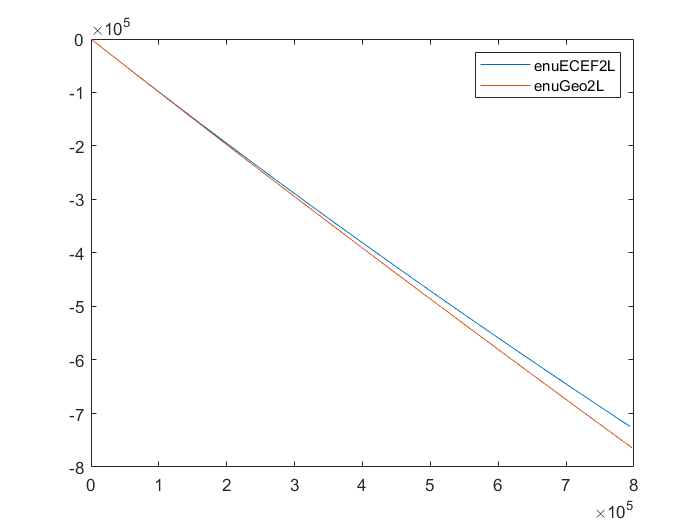

%%%plotting
clf
plot(localfromECEF(:,1),localfromECEF(:,2))
hold on
plot(localfromGeo(:,1),localfromGeo(:,2))
legend('enuECEF2L','enuGeo2L')
hold off

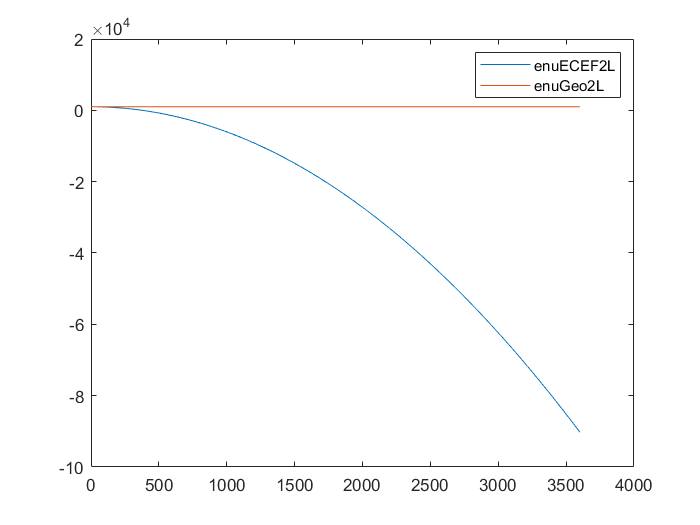

plot(localfromECEF(:,3))
hold on
plot(localfromGeo(:,3))
legend('enuECEF2L','enuGeo2L')
hold off

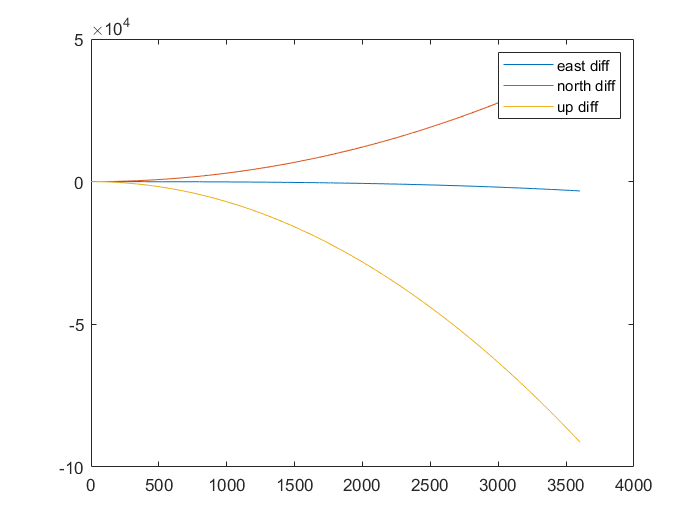

enudiff = localfromECEF - localfromGeo;
plot(enudiff(:,1))
hold on
plot(enudiff(:,2))
plot(enudiff(:,3))
legend('east diff','north diff','up diff')

### Questions:

1. From plot 2, explain why the height goes negative for the enuE2L representation.

The ECEF local coordinates are in flat, euclidan space. As the airplane travels, it follows the cuvature of the earth and seems to dip down below the horizon in the ECEF frame

2. In what sense could you say that both heights (enuE2L and enuG2L heights) are correct in their own ways?

The enuE2L is correct in that if line parallel to the initial direction of the airplane were drawn with a laser, the airplane would end up below that line at the end of its path. The enuG2L height is correct in that the airplane is always 1000m above MSL in its flight path.

3. From plot 3, what’s the maximum distance from the origin of the local level frame you can go in order to keep the maximum altitude difference from being more than 1cm?  (Recall that you’re flying at 300m/s, so knowing time you can also know distance flown).

heightDiffSnippit = localfromGeo(1:10,3)-localfromECEF(1:10,3)

heightDiffSnippit =          0
    0.0071
    0.0282
    0.0635
    0.1129
    0.1765
    0.2541
    0.3459
    0.4518
    0.5718


There is a 7.1mm height difference after 1 second of flight so at (300m/s)/(0.71cm/s) = 422m

it would take 422 meters for the elevation change to reach 1 cm

4. Also, from plot 3, what’s the maximum distance from the origin of the local level frame you can go in order to keep both the east and north difference from being more than 1cm?

From the plot, the limiting factor would be the north difference as it grows faster than the east difference

northDiffSnippit = localfromGeo(1:10,2)-localfromECEF(1:10,2)

northDiffSnippit =          0
   -0.0030
   -0.0119
   -0.0267
   -0.0475
   -0.0741
   -0.1068
   -0.1453
   -0.1898
   -0.2402


300/(northDiffSnippit(2)/-2*100)

ans = 2.0232e+03

The airplane would travel 2.02km before it reached 1 cm of north difference